# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

 **Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

 **Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha: 20/11/2026**

# Tema 4. Ejercicio 4. Características locales y texturas

## Localización de esquinas utilizando el algoritmo FAST

El objetivo de esta práctica es comprobar el comportamiento del detector FAST para localizar esquinas en diferentes tipos de imágenes. Para ello:

- Utilice `corners = detectFASTFeatures(I)` sobre la imagen 'ladrillos1.jpg', y visualice las esquinas sobre ella con la instrucción 

**strongestCorners = corners.selectStrongest(25);**

**plot(strongestCorners.Location(:,1), strongestCorners.Location(:,2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5)**;

- Aumente el número de esquinas seleccionadas y visualizadas para comprobar que las que se incorporan tienen una respuesta menor que las iniciales.

- Pruebe sobre diferentes imágenes (texture-pattern2.png, rice.tif, etc.) para identificar aquellas en las que estas características pueden resultar más útiles.


%% FAST: comparar las esquinas más fuertes
archivosFAST = {'ladrillos1.jpg', 'ladrillos1.jpg', 'texture-pattern2.png', 'rice.tif'};
limites = [25 100 25 25];
numEsquinas = zeros(numel(archivosFAST), 1);
figure
for n = 1:numel(archivosFAST)
    imagen = imread(archivosFAST{n});
    esquinas = detectFASTFeatures(im2gray(imagen));

    % Seleccionamos solo los puntos que existen, aunque pidamos más.
    numEsquinas(n) = esquinas.Count;
    numMostradas = min(limites(n), esquinas.Count);

    subplot(2, 2, n)
    imshow(imagen)
    if numMostradas > 0
        mejores = esquinas.selectStrongest(numMostradas);
        hold on
        plot(mejores.Location(:, 1), mejores.Location(:, 2), 'ro', 'MarkerSize', 10, 'LineWidth', 1.5)
        hold off
    end
    title(sprintf('%s (%d de %d)', archivosFAST{n}, numMostradas, numEsquinas(n)), 'Interpreter', 'none')

    if n == 2 && numMostradas > 25
        % Ordenamos las respuestas para comparar el punto 25 con el 26.
        respuesta = sort(mejores.Metric, 'descend');
        fprintf('FAST en ladrillos1: menor de las 25 primeras = %.4f\n', respuesta(25));
        fprintf('FAST en ladrillos1: mayor de las añadidas = %.4f\n', respuesta(26));
    end

FAST en ladrillos1: menor de las 25 primeras = 144.0000


FAST en ladrillos1: mayor de las añadidas = 143.0000


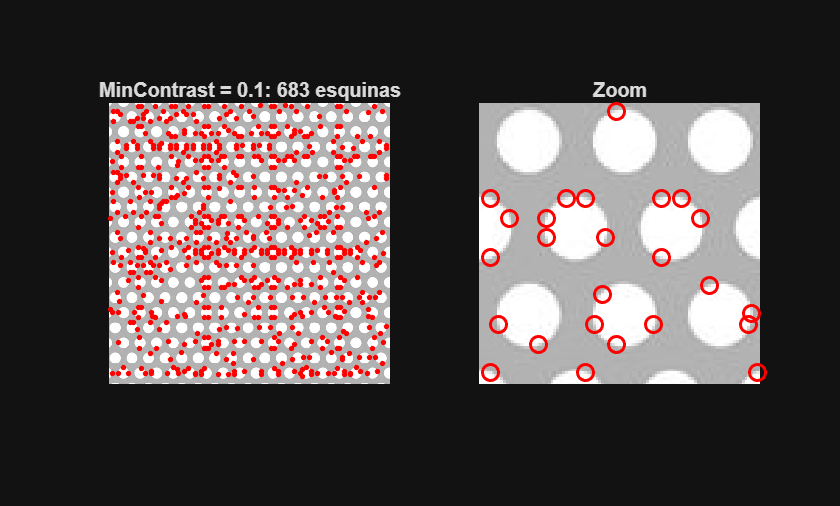

end

%% Prueba extra: FAST en texture-pattern2.png con umbral de contraste más bajo
I = im2gray(imread('texture-pattern2.png'));
esq = detectFASTFeatures(I, 'MinContrast', 0.1);   % umbral 10 % en vez de 20 %

figure
% Panel 1: imagen completa con todos los puntos
subplot(1, 2, 1)
imshow(I)
hold on
plot(esq.Location(:,1), esq.Location(:,2), 'r.', 'MarkerSize', 8)  % puntos pequeños
hold off
title(sprintf('MinContrast = 0.1: %d esquinas', esq.Count))

% Panel 2: zoom a una zona de 100x100 píxeles para ver dónde caen
subplot(1, 2, 2)
imshow(I)
hold on
plot(esq.Location(:,1), esq.Location(:,2), 'ro', 'MarkerSize', 8, 'LineWidth', 1.5)
hold off
xlim([200 300])   % columnas 200 a 300
ylim([200 300])   % filas 200 a 300

title('Zoom')

En ladrillos1.jpg se detectan 920 esquinas. Al mostrar las 25 más fuertes, se concentran en las zonas con juntas y bordes bien marcados. Con 100 aparecen muchos más puntos en esas mismas zonas y en otros bordes. Se aprecia bien en la parte izquierda de la imagen, donde varios círculos se agrupan alrededor de las esquinas de los salientes y de las intersecciones entre juntas, mientras que las zonas oscuras del fondo apenas tienen marcas. La más débil de las 25 primeras esquinas tiene una respuesta de 144, y la más fuerte de las añadidas al ampliar a 100 tiene 143. Por tanto, todas las esquinas que se incorporan tienen una respuesta menor que las iniciales.

En rice.tif se detectan 59 esquinas. La mayoría de las 25 más fuertes caen en las puntas de los granos, donde el contorno cambia bruscamente de dirección, mientras que los lados largos, que son bordes casi rectos, quedan sin marcar.

En texture-pattern2.png no se detecta ninguna esquina con los parámetros por defecto. FAST considera que un píxel es una esquina si, en un círculo de 16 píxeles a su alrededor, hay un arco de al menos 9 píxeles contiguos que son todos más claros o todos más oscuros que él, con una diferencia mínima dada por el umbral MinContrast. Por defecto vale 0,2, es decir, un 20 % del rango de intensidades (unos 51 niveles de gris). En los bordes redondeados de los círculos, la parte del círculo de prueba que cae dentro de la zona clara es aproximadamente la mitad, insuficiente para formar ese arco, y además el contraste entre los círculos y el fondo gris es moderado. 

Al analizar de nuevo texture-pattern2.png reduciendo MinContrast a 0,1, se detectan 683 puntos. Sin embargo, se observa que se sitúan sobre el contorno de los círculos en posiciones irregulares: aunque todos los círculos son idénticos, cada uno tiene un número distinto de puntos y en lugares diferentes de su borde. Esto indica que no corresponden a esquinas reales de la textura, sino a los pequeños escalones que produce la discretización del contorno circular en píxeles, que FAST interpreta como esquinas cuando el umbral de contraste es bajo.

En conclusión, FAST resulta útil en imágenes con esquinas bien definidas y buen contraste, como las juntas y salientes de los ladrillos o los extremos de los granos de arroz, pero no en texturas formadas por contornos redondeados o de bajo contraste como texture-pattern2.png.

## Uso de características LBP para distinguir imágenes con texturas diferentes

El objetivo de este ejercicio es verificar el comportamiento de las caracteristicas LBP en imágenes con texturas diferentes. Para ello:

- Abra y muestre las imágenes texture-canvas.png, gotas.jpg, ladrillos2.jpg, ladrillos3.jpg y ladrillos4.jpg y calcule sus características LBP con la instrucción `LBPImag1 = extractLBPFeatures(Imag1,'Upright',false).`Utilice `'Upright',false` para obtener la variante invariante a rotación de LBP estudiada en teoría.

- Visualice las características con `bar(LBPImag1)`. ¿Se parecen entre sí las características de las distintas imágenes? Utilice la función subplot para visualizar todas las imágenes y características y así poder realizar la comparación fácilmente.

- Calcule la distancia entre las características LBP de ladrillos3.jpg y cada una de las demás imágenes, utilizando la instrucción `DistImag1_2 = norm (LBPImag1 - LBPImag2)`. Compare las distancias obtenidas. ¿Son coherentes con la similitud que se aprecia visualmente entre las texturas? Justifique la respuesta.

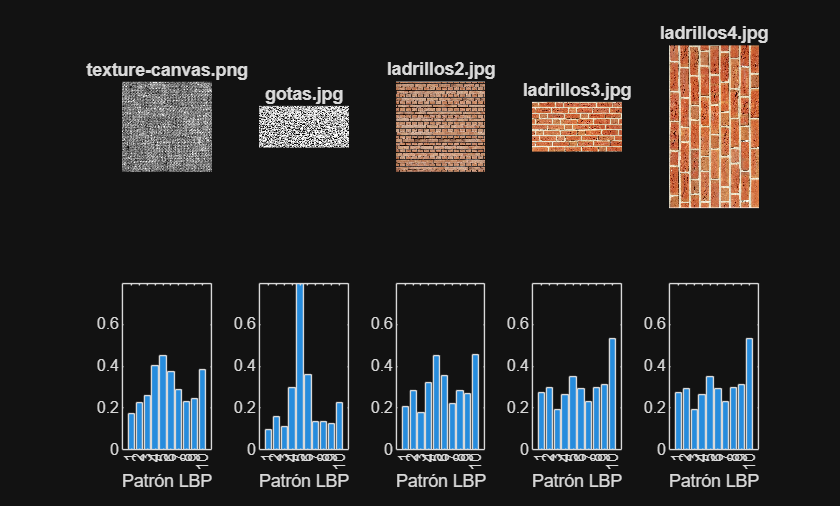



%% LBP: histogramas y distancias entre texturas
archivosLBP = {'texture-canvas.png', 'gotas.jpg', 'ladrillos2.jpg', 'ladrillos3.jpg', 'ladrillos4.jpg'};
numTexturas = numel(archivosLBP);
imagenesLBP = cell(1, numTexturas);
descriptores = cell(1, numTexturas);
for n = 1:numTexturas
    imagenesLBP{n} = imread(archivosLBP{n});
    % Upright=false agrupa patrones que son iguales al rotarlos.
    descriptores{n} = extractLBPFeatures(im2gray(imagenesLBP{n}), 'Upright', false);
end

% Una escala común permite comparar la altura de las barras.
maxBarra = max([descriptores{:}]);
figure
for n = 1:numTexturas
    subplot(2, numTexturas, n)
    imshow(imagenesLBP{n})
    title(archivosLBP{n}, 'Interpreter', 'none')
    subplot(2, numTexturas, numTexturas + n)
    bar(descriptores{n})
    ylim([0 maxBarra])

    xlabel('Patrón LBP')
end

% Comparamos cada descriptor salvo el de la propia imagen de referencia.
referencia = 4;
otras = setdiff(1:numTexturas, referencia);
distancias = zeros(numel(otras), 1);
for n = 1:numel(otras)
    distancias(n) = norm(descriptores{referencia} - descriptores{otras(n)});
end

% Ordena de menor a mayor distancia, es decir, de la más parecida a ladrillos3 a la menos parecida.
[distanciasOrdenadas, orden] = sort(distancias);

tablaLBP = 4×2 table
        'ladrillos4.jpg'    0.0040
        'ladrillos2.jpg'    0.1753
    'texture-canvas.png'    0.2995
             'gotas.jpg'    0.6500


nombresOrdenados = archivosLBP(otras(orden));
tablaLBP = table(nombresOrdenados(:), distanciasOrdenadas, 'VariableNames', {'Imagen', 'DistanciaALadrillos3'})

## Comparación de las texturas

Con los parámetros por defecto (8 vecinos y radio 1), el descriptor LBP invariante a rotación es un histograma de 10 barras. Las nueve primeras cuentan los patrones uniformes según su número de unos, de 0 a 8: los valores extremos corresponden a zonas planas o puntos aislados, y los intermedios a bordes y esquinas. La última barra agrupa todos los patrones no uniformes.

Los histogramas de ladrillos3.jpg y ladrillos4.jpg son prácticamente iguales, con una distancia de solo 0,004. Esto se debe a que ambas imágenes muestran la misma pared: ladrillos4.jpg es ladrillos3.jpg girada 90°, con las hileras en vertical en lugar de en horizontal. Como se ha usado la variante invariante a rotación ('Upright', false), los patrones que solo se diferencian en un giro se cuentan en la misma barra, y girar la imagen apenas modifica el histograma. La pequeña distancia restante se debe principalmente a la compresión JPEG. En ambos casos la barra más alta es la última, porque la superficie rugosa del ladrillo genera muchos patrones irregulares (no uniformes).

La siguiente imagen más parecida es ladrillos2.jpg (0,175). Comparte la estructura de ladrillos y juntas, aunque los ladrillos tienen distinto tamaño y aspecto. La tela queda más lejos (0,300): su textura es un entramado fino de hilos repartido por toda la superficie, sin las juntas rectas y repetidas de los ladrillos. La imagen más distinta es gotas.jpg (0,650), formada por contornos pequeños y redondeados con reflejos claros sobre un fondo oscuro. Su histograma tiene un pico muy marcado en la quinta barra, que corresponde a patrones con cuatro unos, es decir, la mitad de los vecinos más claros que el centro. Según la teoría, ese tipo de patrón es característico de los bordes, lo que encaja con la gran cantidad de contornos de las gotas.